## project2.mlx, Leo Berman & Justin Ok, 10/5/2023

# Signals Project 2

Leo Berman & Justin Ok

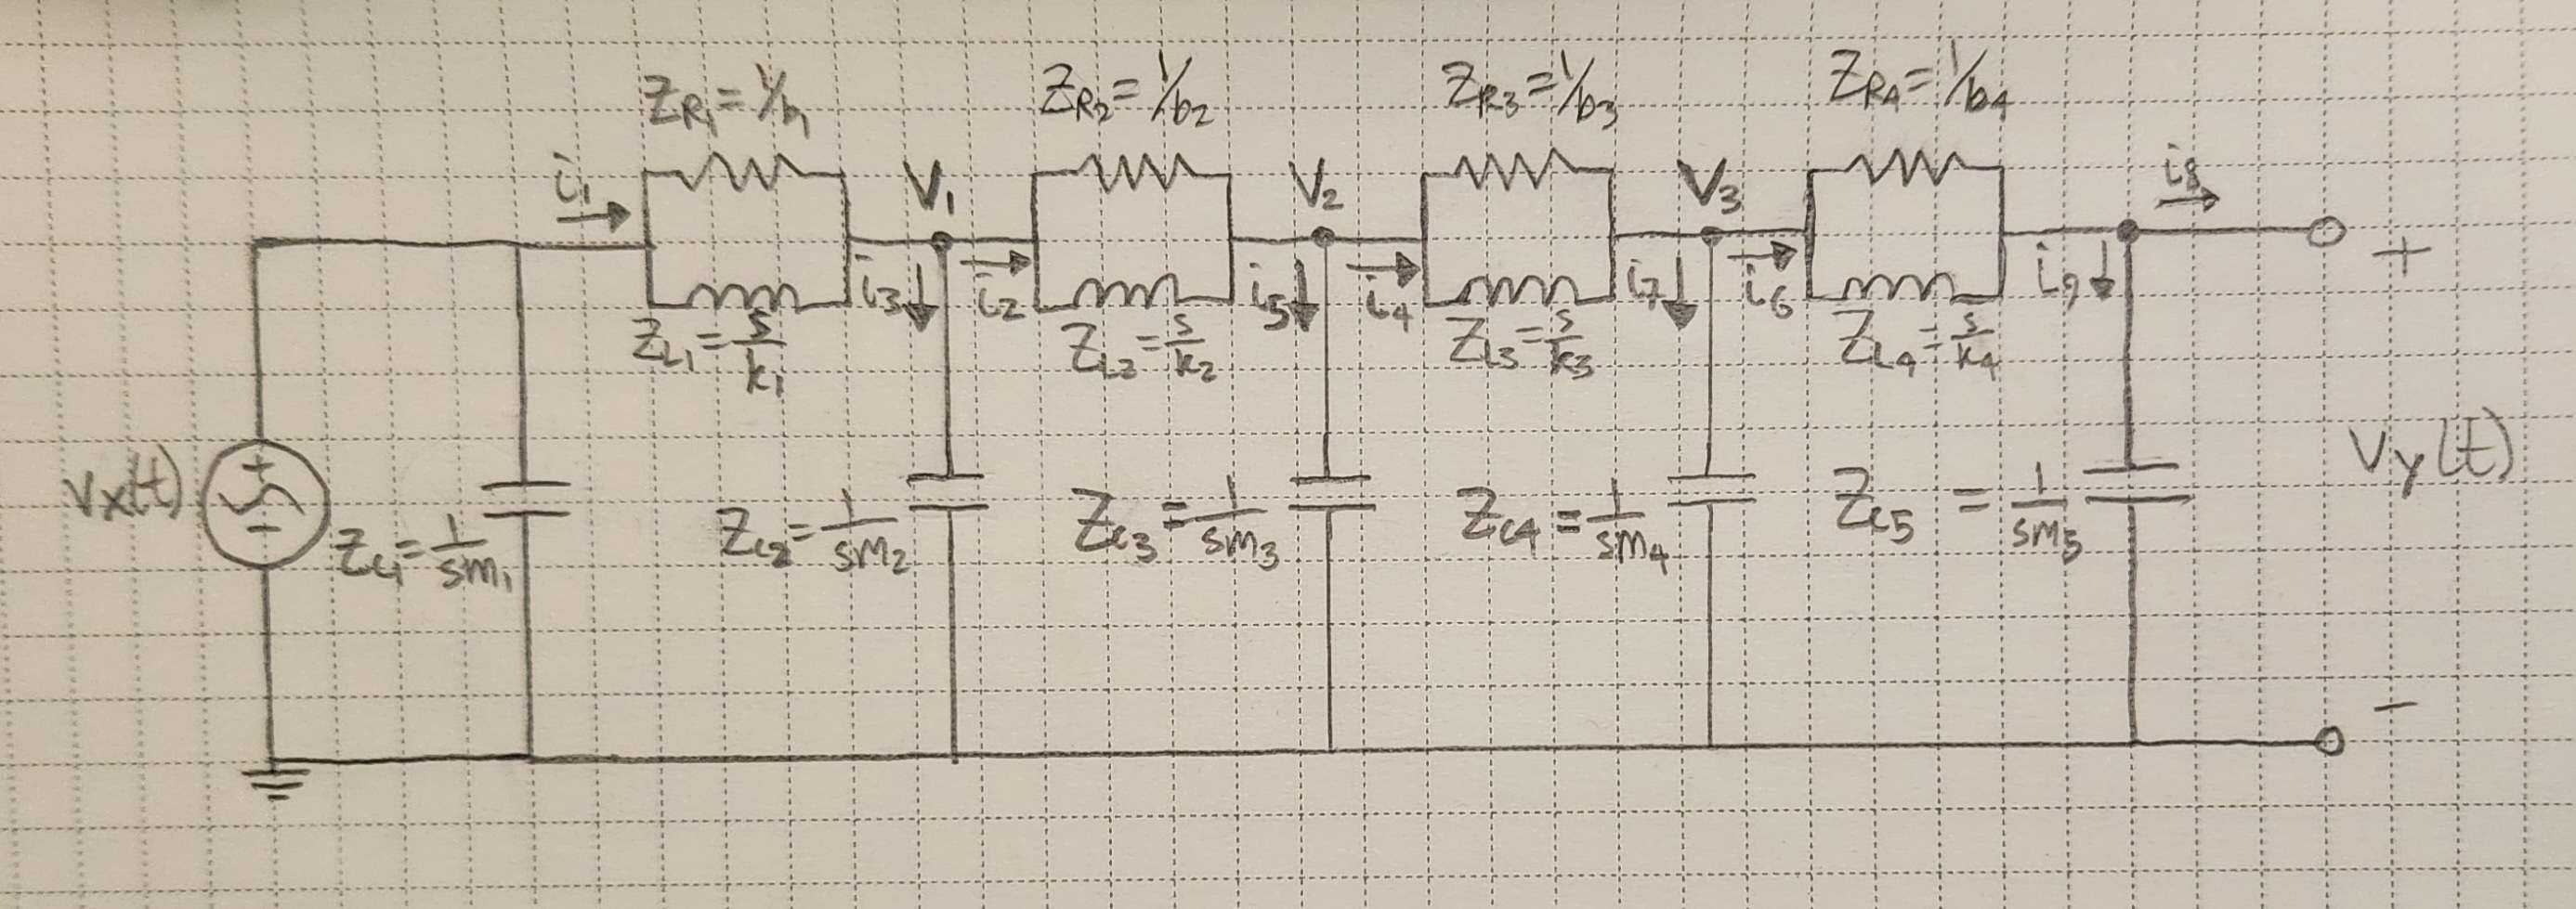    

## Symming s, t, setting input as impulse to find transfer function

clear all
close all
clc
syms s t

## Finding minimum spring constant to hold a human being

m_human = 28.8+22+26.35+6.76;
g = 9.8; % m/s^2 gravitational constant
weight_human = m_human*g;
x = .02; % setting the displacement to a couple of centimeters for a firm chair
spring_constant = weight_human/x;

## Physical properties of the human/chair combo

b = 90;
k = 3500;
m1 = 30; % chair weight kg
k1 = spring_constant; % spring constant of chair
b1 = 5; % damping constant of chair
m2 = 8.164; % lower torso kg
k2 = k; % spring constant of bones
b2 = b; % damping constant of soft tissue
m3 = 11.953; % middle torso kg
k3 = k; % spring constant of bones
b3 = b; % damping constant of soft tissue
m4 = 11.654; % upper torso kg
k4 = k; % spring constant of bones
b4 = b; % damping constant of soft tissue
m5 = 5.018; % head weight kg

## Circuit conversion into s domain

ZC1 = 1/(s*m1);
ZL1 = s/k1;
ZR1 = 1/b1;
ZC2 = 1/(s*m2);
ZL2 = s/k2;
ZR2 = 1/b2;
ZC3 = 1/(s*m3);
ZL3 = s/k3;
ZR3 = 1/b3;
ZC4 = 1/(s*m4);
ZL4 = s/k4;
ZR4 = 1/b4;
ZC5 = 1/(s*m5);
ZRL1 = (1/ZR1 + 1/ZL1)^-1;
ZRL2 = (1/ZR2 + 1/ZL2)^-1;
ZRL3 = (1/ZR3 + 1/ZL3)^-1;
ZRL4 = (1/ZR4 + 1/ZL4)^-1;

## Nodal

% Simulating Variables
syms I1 I2 I3 I4 I5 I6 I7 I8 I9

% Nodal Equations
eq1 = I1 == I2 + I3;
eq2 = I2 == I4 + I5;
eq3 = I4 == I6 + I7;
eq4 = I6 == I8 + I9;

% Defining our impulse
vx = dirac(t);
Vx = laplace(vx);
syms V1 V2 V3 VY

% Defining Current's
eq5 = I1 == (Vx-V1)/ZRL1;
eq6 = I2 == (V1-V2)/ZRL2;
eq7 = I3 == V1/ZC2;
eq8 = I4 == (V2-V3)/ZRL3;
eq9 = I5 == V2/ZC3;
eq10 = I6 == (V3-VY)/ZRL4;
eq11 = I7 == V3/ZC4;
eq12 = I8 == 0;
eq13 = I9 == VY/ZC5;

% Getting solution Matrixes
eqns = [eq1 eq2 eq3 eq4 eq5 eq6 eq7 eq8 eq9 eq10 eq11 eq12 eq13];
vars = [I1 I2 I3 I4 I5 I6 I7 I8 I9 V1 V2 V3 VY];

% Solving the system of equations
sol = solve(eqns,vars);

% Setting Transfer Functions For head and parts of the torso
Hs_head = partfrac(sol.VY);
Hs_hightorso = partfrac(sol.V3);
Hs_lowtorso = partfrac(sol.V2);

## Getting the resonant frequency of our system

% Plotting the frequencies in order to determine where we are amplifying
% frequencies to make sure we aren't distrubing any organs
%getfreqresp(Hs_head,'head')
%getfreqresp(Hs_hightorso,'upper torso')
%getfreqresp(Hs_lowtorso,'lower torso')

## Response to u(t)-u(t-1) going up a curb

% Plotting the convolution of the head with a curb(6 inches) in .5 seconds
% curbmax = invsout(Hs_head,.1524*(heaviside(t)-heaviside(t-.5)))

## Response to going over a speed bumb

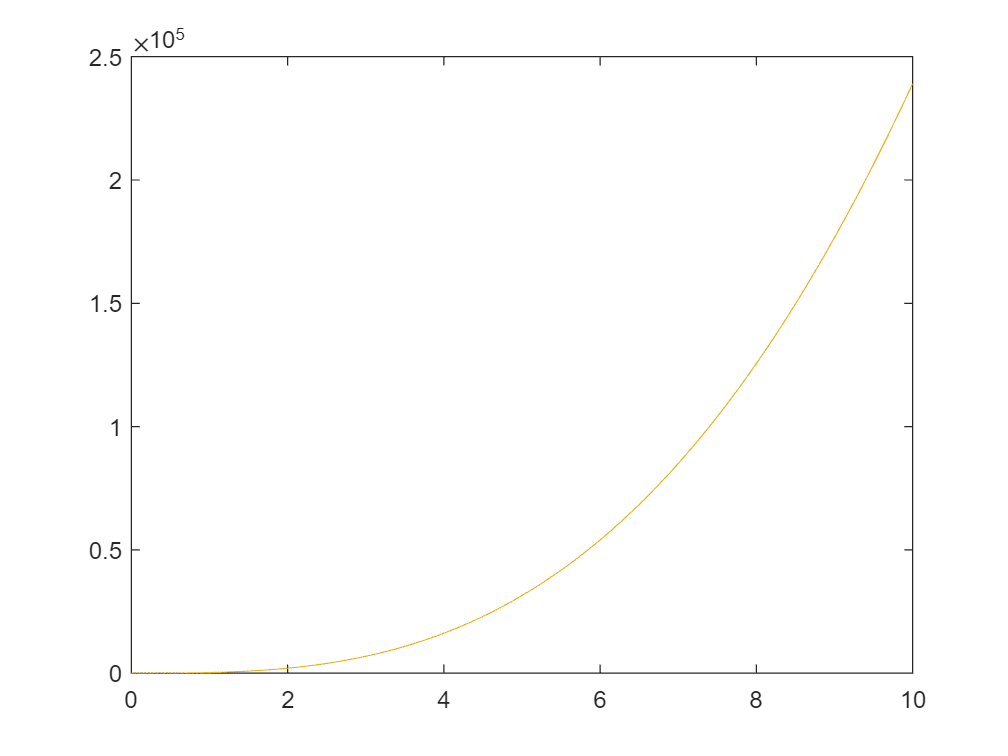

Incorrect number or types of inputs or outputs for function 'laplace'.

Error in project2>invsout (line 106)
    out = ilaplace(transfunc*laplace(in))*heaviside(t);

% Plotting the convolution of the head with a speed bumb(6 inches tall, 24
% inches wide) in 1 second use exponentials on modeling speedbumps
bumpmax = invsout(Hs_head,.1524*(1/(t^2)*heaviside(t)-1/(t^2)*heaviside(t-1)))

## Trying to get the response via laplaces

function[maxim]=invsout(transfunc,input)
    syms t s
    % 10 second linspace
    t1 = linspace(.001,10,1000);
    
    % getting the transfer function
    [n, d]=numden(transfunc);
    coeffs_n=fliplr(double(coeffs(n,'All')));
    coeffs_d=fliplr(double(coeffs(d,'All')));
    mytf=tf(coeffs_n,coeffs_d);
    in = double(subs(input,t,t1));
    %save in.mat in -mat
    yt1 = lsim(mytf,in,t1);
    plot(t1,yt1);
    hold on

    % hold on
    % Convolves the input with the output
    out = ilaplace(transfunc*laplace(input))*heaviside(t);

    % Differentiates in order to get the first derivative of velocity
    % (acceleration)
    accel = diff(out);

    % Plots the input velocities as well as acceleration
    fplot(in,[0 10]);
    hold on;
    fplot(accel,[0 10]);
    hold on;
    legend('output velocity', 'input','acceleration');
    hold off;

 
    difs = subs(accel,t,t1);
    maxim=double(real(max(difs)));
end

## Bode Plot

function[]=getfreqresp(transfunc,string)
    
    % getting the transfer function
    [n, d]=numden(transfunc);
    coeffs_n=fliplr(double(coeffs(n)));
    coeffs_d=fliplr(double(coeffs(d)));
    Hs_fromtf=tf(coeffs_n,coeffs_d);
    
    % plots the bode diagram
    bode(Hs_fromtf); 
    title(string)
end
